# Sygnały cyfrowe

#### Mateusz Wójcik, 5.12.2024

Zajęcia dotyczą sygnałów cyfrowych, ograniczeń z nimi związanych, takich jak utrata pewnej liczby informacji oraz operacji jakich na takich sygnałach jesteśmy w stanie przeprowadzać. W trakcie zajęć zapoznano się z konspektem dotyczącym sygnałów cyfrowych, z wykorzystaniem takich funkcji jak **delta Kroneckera** oraz **skok jednostkowy**, oraz np. wzór na splot sygnału spróbkowanego. Zajęcia polegały na rozwiązaniu kolejnych zadań i odpowiedzeniu na pytania.

## Zad 1

Z podstawami programu Matlab zapoznawano się na dotychczasowych zajęciach.

## Zad 2

Wygenerowano na dwóch wykresach skoki jednostkowe przesunięte względem siebie.

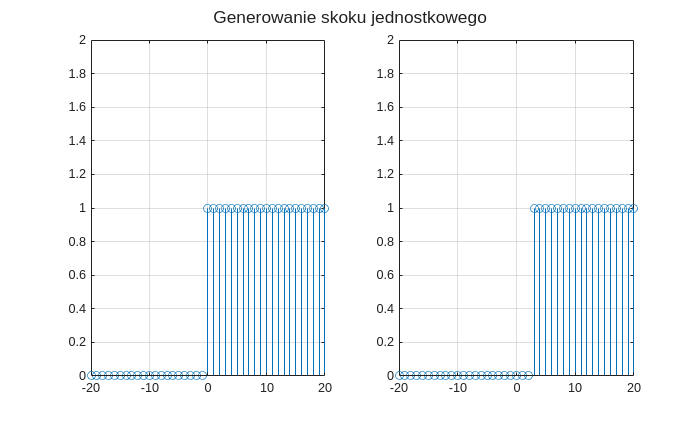

N = 20;
t = -N:N;
u0 = double(t >= 0);
u3 = double(t >= 3);
figure()
subplot(121)
stem(t,u0)
grid on
axis([-20 20 0 2])

subplot(122)
stem(t,u3)
grid on
axis([-20 20 0 2])
sgtitle("Generowanie skoku jednostkowego")

## Zad 3

Wygenerowanie dwóch delt Kroneckera przesuniętych w czasie.

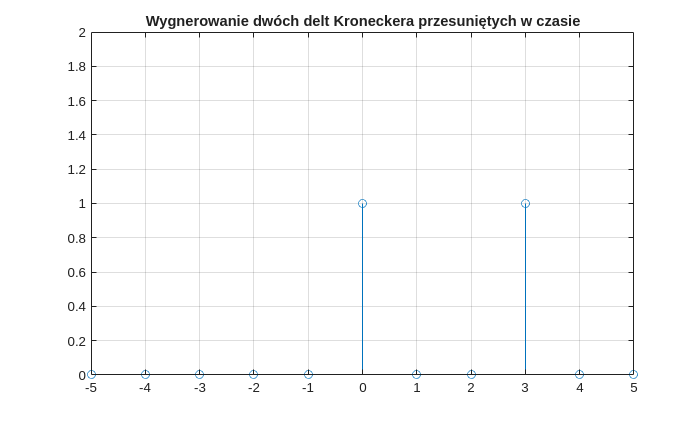

N = 5;
t = -N:N;
u0 = double(t == 0);
u3 = double(t == 3);
signal = u0 + u3;
figure()
stem(t,signal)
title("Wygnerowanie dwóch delt Kroneckera przesuniętych w czasie")
grid on
axis([-N N 0 2])

## Zad 4

Wygnerowanie różnicy skoków jednostkowych przesuniętych w czasie.

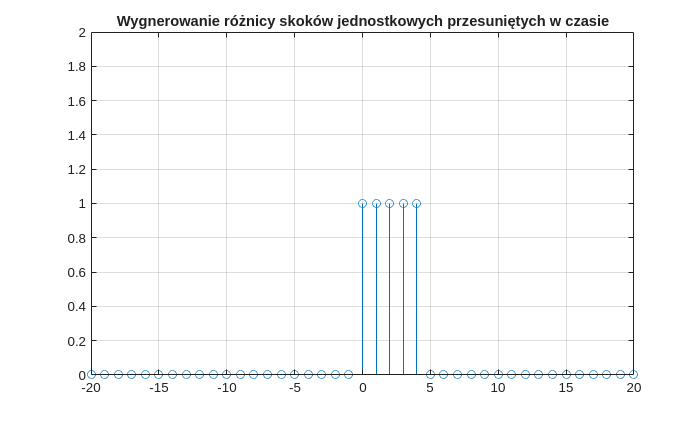

N = 20;
t = -N:N;
u0 = double(t >= 0);
u5 = double(t >= 5);
signal = u0 - u5;
figure()
stem(t,signal)
title("Wygnerowanie różnicy skoków jednostkowych przesuniętych w czasie")
grid on
axis([-N N 0 2])

## Zad 5

Generowanie sinusoid o różnym czasie próbkowania.

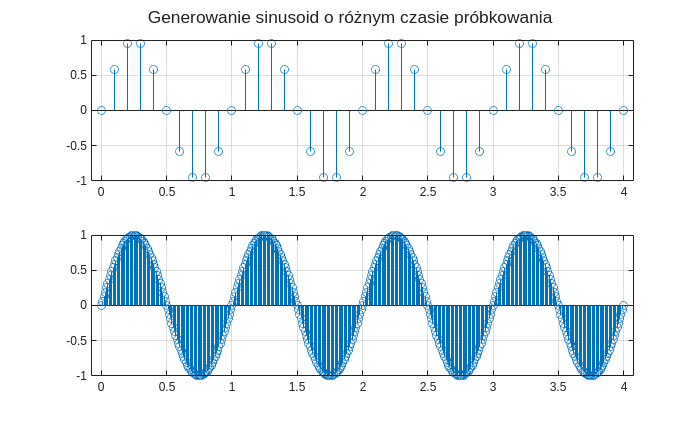

t1=0:1/10:4;
t2=0:1/100:4;

sin1 = sin(2*pi*t1);
sin2 = sin(2*pi*t2);

figure()
subplot(211)
stem(t1,sin1)
grid on

subplot(212)
stem(t2,sin2)
grid on
sgtitle("Generowanie sinusoid o różnym czasie próbkowania")

## Zad 6

Generowanie sinusoid o różnym czasie próbkowania.

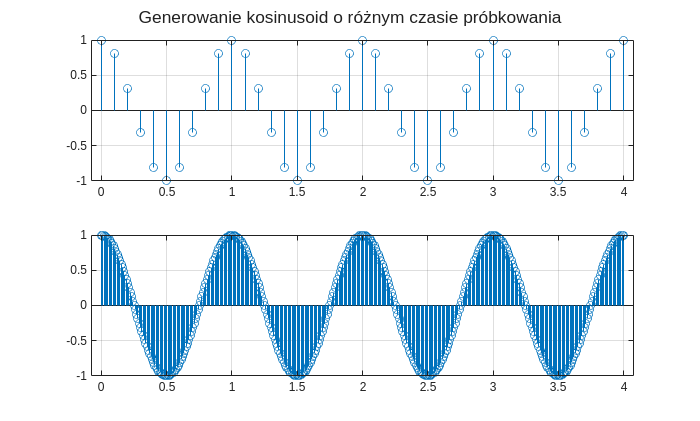

t1=0:1/10:4;
t2=0:1/100:4;

cos1 = cos(2*pi*t1);
cos2 = cos(2*pi*t2);

figure()
subplot(211)
stem(t1,cos1)
grid on

subplot(212)
stem(t2,cos2)
grid on
sgtitle("Generowanie kosinusoid o różnym czasie próbkowania")

## Zad 7

Generowanie rozkładu Gaussa.

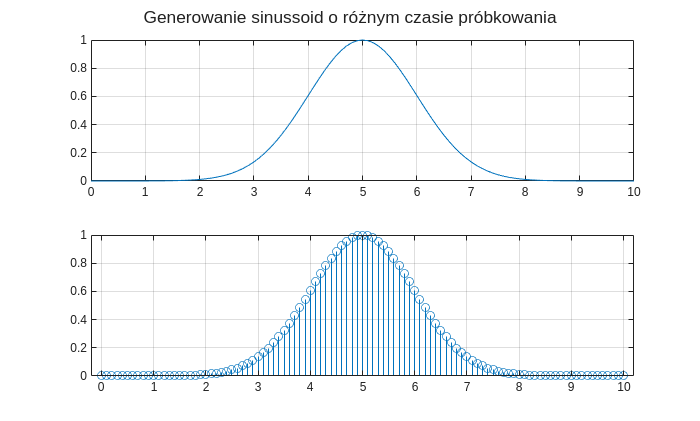

t = 0:0.1:10.;
sig = gaussmf(t,[1 5]);


figure()
subplot(211)
plot(t,sig)
grid on

subplot(212)
stem(t,sig)
grid on
sgtitle("Generowanie sinussoid o różnym czasie próbkowania")

## Zad 8

Wygenerowanie iloczynu sygnałów y1 i y2.

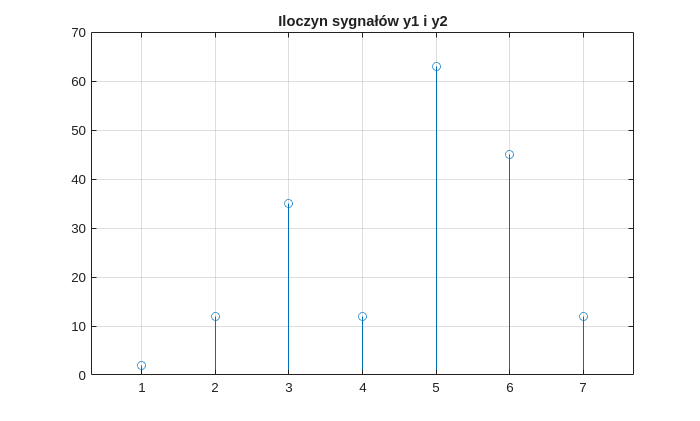

y1=[1,3,5,6,7,9,2];
y2=[2,4,7,2,9,5,6];
y = y1.*y2;
figure()
stem(y)
grid on
title("Iloczyn sygnałów y1 i y2")

## Zad 9

Generowanie odpowiedzi impulsowej dla wartości a=[1], b=[1 -0.5 0.7].

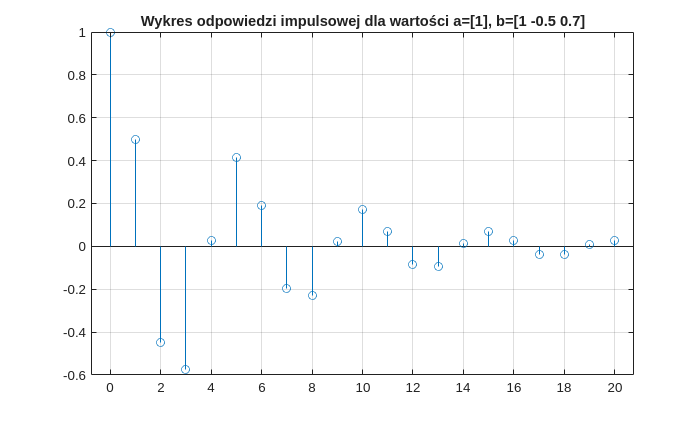

n=0:20;
x=[1,zeros(1,20)];
a=1;
b=[1 -0.5 0.7];
y=filter(a,b,x);
stem(n,y)
grid on
title("Wykres odpowiedzi impulsowej dla wartości a=[1], b=[1 -0.5 0.7]")

## Zad 10

Generowanie sygnału sinusoidalnego.

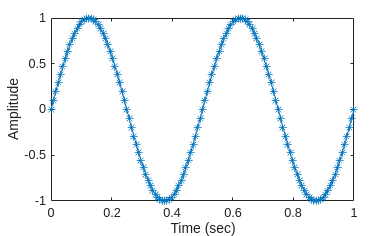

n=128;
k=0:n;
t=k/128; 
A = 1;
fo = 2;
p = 0;
y=A*sin((2*pi*fo*t)+p);

figure()
plot(t,y, "*-")
xlabel('Time (sec)')
ylabel('Amplitude')

## Zad 11

Generowanie sygnału sinusoidalnego.

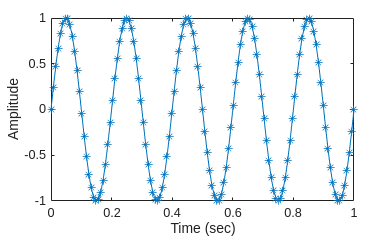

n=128;
k=0:n;
t=k/128; 
A = 1;
fo = 5;
p = 0;
y=A*sin((2*pi*fo*t)+p);


figure
plot(t,y, "*-")
xlabel('Time (sec)')
ylabel('Amplitude')

## Zad 12

Generowanie sygnału pikokształtnego dla częstotliwości próbkowania fs = 100.

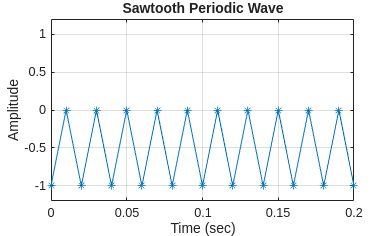

fs = 100;
t = 0:1/fs:1.5;
y = sawtooth(2*pi*50*t);

figure()
plot(t,y,"*-")
axis([0 0.2 -1.2 1.2])
grid on
xlabel('Time (sec)')
ylabel('Amplitude')
title('Sawtooth Periodic Wave')

Można zauważyć, że z powodu zbyt małej częstotliwości próbkowani został tutaj przedstawiony sygnał tylko o wartościach ujemnych.

## Zad 13

Generowanie sygnału prostokątnego dla częstotliwości próbkowania fs = 500.

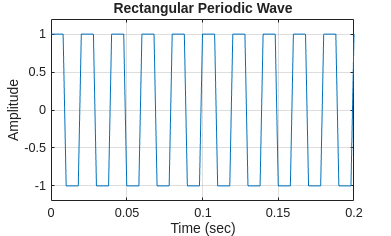

fs = 500;
t = 0:1/fs:1.5;
y = square(2*pi*50*t);

figure()
plot(t,y)
axis([0 0.2 -1.2 1.2])
grid on
xlabel('Time (sec)')
ylabel('Amplitude')
title('Rectangular Periodic Wave')

Można zauważyć, że dla sygnału prostokątnego zbocze nie jest idealnie pionowo nachylone, co jest związane z odległością pomiędzy kolejnymi punktami.

## Zad 14

Generowanie impulsu trójkątnego i prostokątnego o szerokości 0.08.

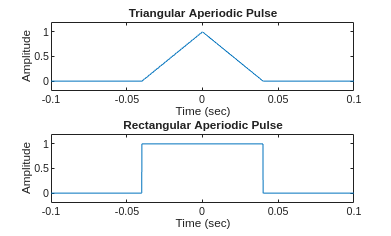

fs = 10000;
t = -1:1/fs:1;
x1 = tripuls(t,80e-3);
x2 = rectpuls(t,80e-3);
subplot(2,1,1)
plot(t,x1)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')
title('Triangular Aperiodic Pulse')
subplot(2,1,2)
plot(t,x2)
axis([-0.1 0.1 -0.2 1.2])
xlabel('Time (sec)')
ylabel('Amplitude')zn
title('Rectangular Aperiodic Pulse')

## Pytania

**1) W jaki sposób reprezentujemy sygnały cyfrowe na komputerze i w Matlabie?**

Sygnały cyfrowe na komputerze są reprezentowane jako pewien określony ciąg zer i jedynek, tzn. bitów informacji. Matlab jest kolejną warstwą abstrakcji (po systemie operacyjnym, itd.) między komputerm, a użytkownikiem, która pozwala na przechowywanie tablic liczb w postaci zmiennoprzecinkowej, która jest określona bezpośrednio w odpowiedniej normie międzynarodowej. To pozwala użytkownikowi na przetwarzanie sygnałów cyfrowych w sposób bardziej intuicyjny i zbliżony do matematycznych rozważań.

**2) Jakie informacje może zawierać sygnał cyfrowy? Wymienić jakieś przykłady?**

Sygnał cyfrowy przenosi informacje w postaci dyskretnych wartości, takich jak "0" i "1". Może zawierać dane tekstowe (np. wiadomości e-mail), multimedialne (dźwięk MP3, wideo, obrazy JPEG), pomiarowe (wyniki z czujników), oraz sieciowe (pakiety TCP/IP). W automatyce steruje urządzeniami (PLC, silniki), a w systemach komputerowych przenosi dane binarne (instrukcje, pliki). Służy do synchronizacji czasowej, przesyłania danych szyfrowanych (HTTPS) czy informacji o lokalizacji (GPS). Może sygnalizować stan systemu (flagi, błędy) i działa zgodnie z określonymi protokołami lub standardami, które definiują jego fomat i interpretację.

**3) Czy Pana/Pani zdaniem da się zamienić sygnały cyfrowe na sygnały analogowe?**

Tak, istnieje cała grupa komponentów - przetwornik cyfrowo-analogowe (DAC), która realizuje tą operację, a następnie przenosi analogowy sygnał napięcia np. na drgania membrany głośnika, które powodują dźwięk. Dzieje się to oczywiście z pewną rozdzielczością, która zależy od przetwornika, który wykorzystuje się w danej aplikacji.

**4) Na czym polega różnica pomiędzy przekazem analogowym a cyfrowym w telewizji?**

Telewizja analogowa i cyfrowa różnią się sposobem transmisji sygnału, co wpływa na jakość odbioru i funkcjonalność. Telewizja analogowa przesyła obraz i dźwięk w sposób ciągły za pomocą fal elektromagnetycznych. Jest prosta w odbiorze, a starsze telewizory nie wymagają dodatkowego sprzętu. Jednak jej jakość zależy od siły sygnału i warunków przesyłu sygnału (np. warunków atmosferycznych) – zakłócenia powodują szumy i zniekształcenia. Analogowe pasmo częstotliwości pozwala na przesył jednego kanału, co jest nieefektywne. Z kolei telewizja cyfrowa przesyła skompresowane dane, co umożliwia transmisję wielu kanałów w jednym paśmie. Oferuje wysoką jakość obrazu i dźwięku, obsługę HD i dodatkowe funkcje, takie jak elektroniczny przewodnik po programach (EPG). Jednak cyfrowy sygnał wymaga odpowiedniego sprzętu i stabilności – przy jego braku obraz może całkowicie zanikać. Telewizja cyfrowa lepiej wykorzystuje pasmo, ale starszy sprzęt wymaga dekoderów, co może być utrudnieniem.

**5) Czy sygnał cyfrowy może mieć wiele wymiarów?**

Sygnał cyfrowy może mieć wiele wymiarów. Przykładem wielowymiarowości jest są np. obrazy cyfrowe filmy, dźwięk wielokanałowy (np. stereo lub surround) czy sygnały w systemach MIMO w telekomunikacji. W systemach wielokanałowych każdy kanał jest traktowany jako osobny wymiar, a w obrazach cyfrowych piksel może być wektorem (np. w przestrzeni RGB, lub innych sposobach kodowania koloru). W zastosowaniach sygnały wielowymiarowe pojawiają się w obrazowaniu medycznym (np. tomografia 3D lub 4D z czasem),czy w analizie danych z sensorów IoT (np. temperatura, wilgotność, ciśnienie). 

**6) Czy częstotliwość próbkowania jest ważna?**

Na podstawie tych i wcześniejszych zajęć laboratoryjnych można odpowiedzieć na to pytanie twierdząco. W zależności z jakim sygnałem mamy do czynienia, częstotliwość próbkowania jest kluczowa jeżeli liczymy na odpowiednie odwzorowanie sygnału, o czym mówi twierdzenie Nyquista-Shannona. W tym laboratorium można było zauważyć negatywny wpływ doboru złej częstotliwości m.in. w zadaniu 12.

# Wnioski

Na zajęciach laboratoryjnych ugruntowano wiedzę na temat sygnałów cyfrowych i ich ograniczeń dotyczących wiernego odwzorowania sygnałów analogowych. Oprócz tego powtórzono i utrwalono wiedzę z generowania podstawowych przebiegów funkcyjnych. Na pewno trzeba mieć świadomość, że przechodząc z sygnału analogowego na cyfrowy bezpowrotnie tracimy część informacji, która była zawarta w tym sygnale. Natomiast będąc świadomi tych ograniczeń i konsekwencji jakie ze sobą niosą jesteśmy w stanie efektywnie wykorzystywać sygnały cyfrowe i uzyskiwać bardzo dobre przybliżenia.